# SVM Regression with kernel

## Generate some dataset with non linearly separable classes

Classes can be non linearly separable in $R^2$, but they can be separable if "mapped" into higher dimensional space.

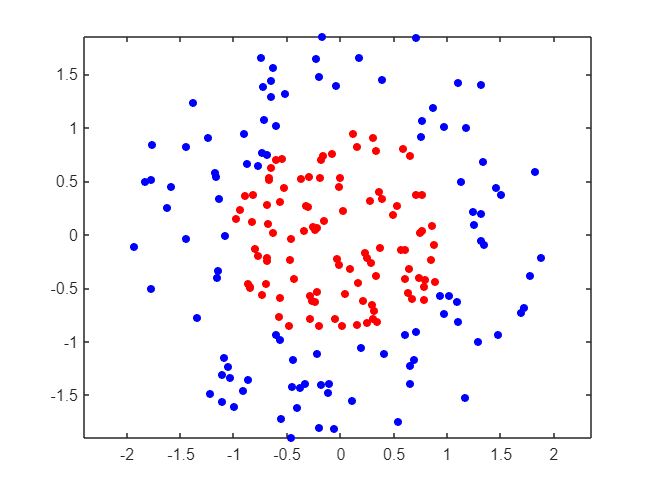

r = sqrt(rand(100 ,1));                 % random radius
t = 2*pi*rand(100 ,1);                  % random angle
data1 = [r.* cos(t), r.* sin(t)];       % points of class -1 (RED )

r2 = sqrt(3*rand(100 ,1) +1);           % random radius for ring
t2 = 2* pi*rand (100,1);                % random angle for ring
data2 = [r2 .* cos(t2), r2 .* sin(t2)]; % points of class +1 ( BLUE )
data3  = [data1; data2];                % merge data together

figure
plot(data1(:,1), data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1), data2(:,2),'b.','MarkerSize',15)
axis equal
hold off

## Define custom kernel

$K\left(U,V\right)=<\varphi \left(U\right),\varphi \left(V\right)>$        ($\varphi \;\mathrm{is}\;\mathrm{unknown}$)

type mysigmoid.mlx    % custom kernel definition

function K = mysigmoid(U,V)       % custom kernel definition
gamma = 0.5;
c = -1;
K = tanh(gamma*U*V' + c);          % U = mxp, V = nxp, K = mxn
end


## Run Support Vector Regression with custom kernel

y = franke(data3(:,1), data3(:,2));
regSVM_mykernel = fitrsvm(data3, y, 'KernelFunction','mysigmoid', ...
                      'BoxConstraint',10, 'Epsilon',0.04, 'Standardize',true);
 
check_conv = regSVM_mykernel.ConvergenceInfo.Converged

check_conv = logical
   1


disp("Number of support vectors : " + numel(regSVM_mykernel.Alpha))

Number of support vectors : 199


## Prediction on a uniform grid

[x1Grid,x2Grid] = meshgrid(min(data3(:,1)):d:max(data3(:,1)),...
    min(data3(:,2)):d:max(data3(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

response = predict(regSVM_mykernel, xGrid);


## Visualization

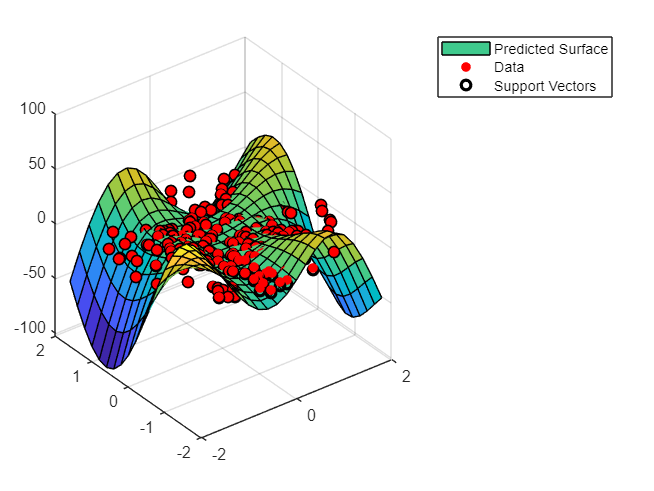

figure
surf(x1Grid, x2Grid, reshape(response,size(x1Grid))  )
hold on
scatter3(data3(:,1), data3(:,2),y, 'r', 'filled'), hold on
supVec = data3(regSVM_mykernel.IsSupportVector,:);
plot(supVec(:,1), supVec(:,2), 'ko', 'LineWidth',2)
legend("Predicted Surface", "Data", "Support Vectors")